## 模拟退火算法在仿真优化中的应用（与KN算法对比）

本文在Alrefaei(1999)的基础上，展示了一种基于模拟退火的的仿真优化方法，并将其与KN算法进行对比。

clear
rng(1)
global N X x_index V cumulative_sum samplesize f_hat

假设我们需要对以下仿真过程的参数进行优化，

parameter = 1

parameter = 1

simulation(parameter) %仿真过程示例在文末

ans = 0.5490

此处示例的仿真过程使用了HW4的仿真过程，以便与KN算法进行对比，即方差与均值成正比的正态分布

按照HW4，可选参数为有限离散值1～10

由于采用全集作为探索邻域，因此参数的排布顺序不影响退火算法的搜索

N = 10;
delta = 0.1; %indifference-zone parameter
X = 1:10;


参数设置

V = repelem(0,N);
cumulative_sum = repelem(0,N);
samplesize = repelem(0,N);

Step 0： initialization

tic %计时

x_index = randsample(N,1);
V(x_index) = V(x_index)+1;

Step 1: epoch

epoch(0);

Step 2: cooling

for k = 1:5000
    epoch(k)
end

'down'

ans = 'down'

Step 3: optimal

[M,I] = min(f_hat) ;
[m,i] = max(V) ;

toc %结束计时

历时 0.213009 秒。


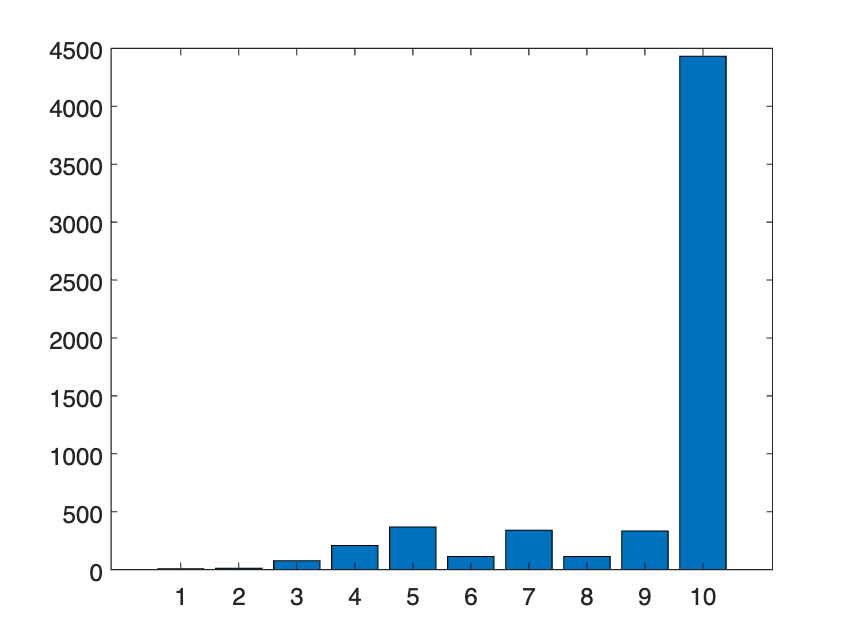

bar(X,V)

Step 1: epoch

function epoch(k)
global N X x_index V cumulative_sum samplesize f_hat

%退火冷却，温度随着迭代降低
T_k = 1/log(10+k); 
L_k = 1 ;

%确定x取值
x = X(x_index);

%邻域（此处选择全集）内随机选择候选参数
z_index = randsample(N,1);
while z_index == x_index
    z_index = randsample(N,1);
end
z = X(z_index);

%抽样
for i = 1:L_k
    cumulative_sum(z_index) =  cumulative_sum(z_index) + simulation(z);
    cumulative_sum(x_index) =  cumulative_sum(x_index) + simulation(x);
end

%记录抽样数量
samplesize(x_index) = samplesize(x_index)+L_k;
samplesize(z_index) = samplesize(z_index)+L_k;

%计算估计值
f_hat = cumulative_sum./samplesize;

%计算接受候选参数的概率
Delta = exp(-max(0,f_hat(z_index)-f_hat(x_index))/T_k);

%更新参数
if rand(1) <= Delta
    x_index = z_index;
end

%纪录访问次数
V(x_index) = V(x_index)+1;

end

仿真过程

function output = simulation(parameter)
    output = - (randn()*parameter + parameter/10);
end

参考文献

Alrefaei, M. H., & Andradóttir, S. (1999). A Simulated Annealing Algorithm with Constant Temperature for Discrete Stochastic Optimization. *Management Science*, *45*(5), 748–764. [https://doi.org/10.1287/mnsc.45.5.748](https://doi.org/10.1287/mnsc.45.5.748)